sed

Lagrange polynomials in 2D

[/home/joaquin/Desktop/CURRENT_TASKS/PAPERS_2020_onwards/OptimalECM/PolyIMPLEMENT.tex](matlab:open('/home/joaquin/Desktop/CURRENT_TASKS/PAPERS_2020_onwards/OptimalECM/PolyIMPLEMENT.tex'))

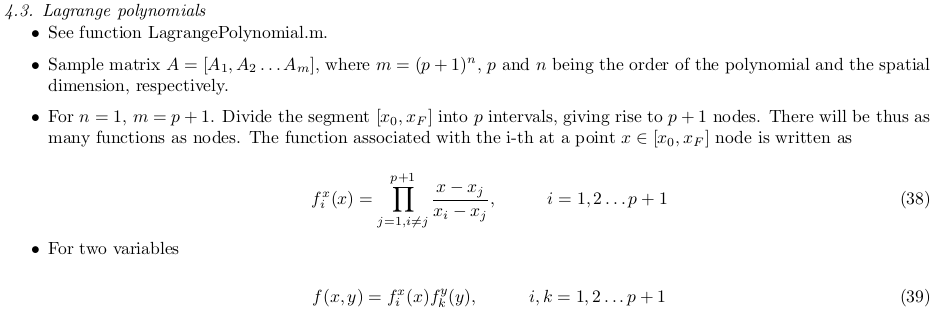

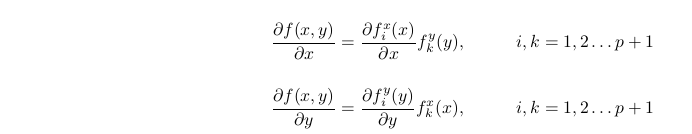

f = N_I 

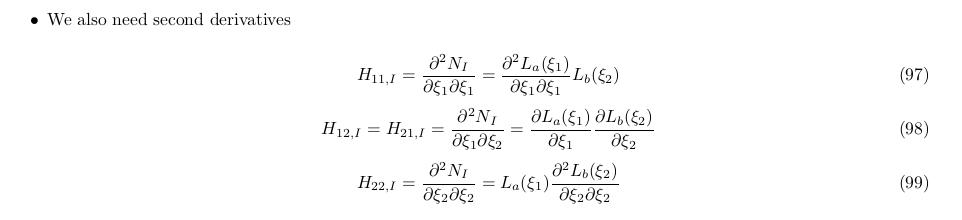

iacum = 1;
for idimx = 1:size(Ax,1)
    for idimy = 1:size(Ay,1)
        A(iacum,:) =  Ax(idimx,:).*Ay(idimy,:) ;
        
        dA_x(iacum,:) =  dAx(idimx,:).*Ay(idimy,:) ;
        
        dA_y(iacum,:) =  Ax(idimx,:).*dAy(idimy,:) ;
        
        H_xx(iacum,:) =  DATAOUT_x.ddf(idimx,:).*Ay(idimy,:) ;
        H_yy(iacum,:) =   Ax(idimx,:).*DATAOUT_y.ddf(idimy,:) ;
        
        H_xy(iacum,:) =  dAx(idimx,:).*dAy(idimy,:) ;
        
        iacum = iacum + 1;
    end
    
end
